path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.0382M\*.csv")

path = 23×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.0382M'

sampleConcentration = '0.0382M'

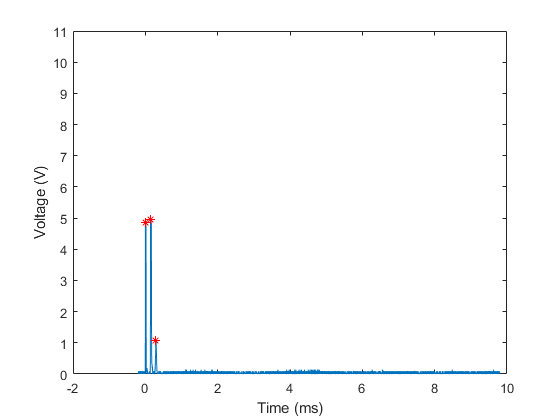

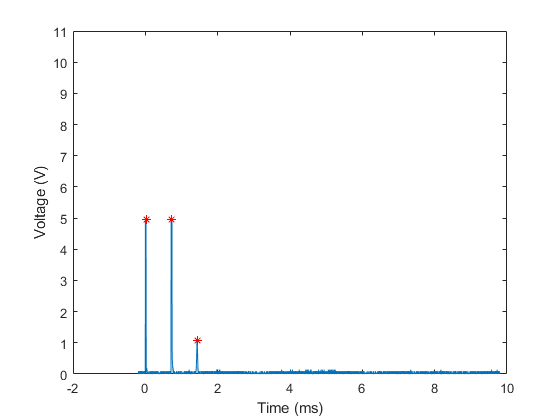

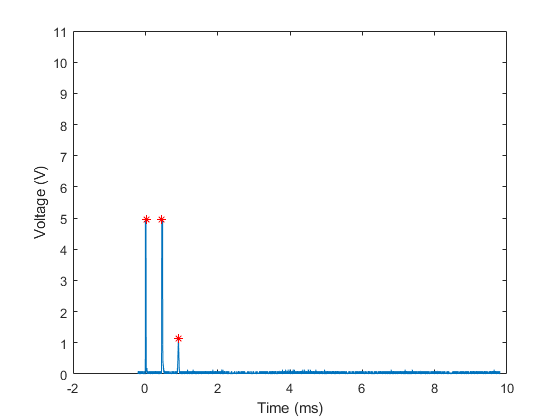

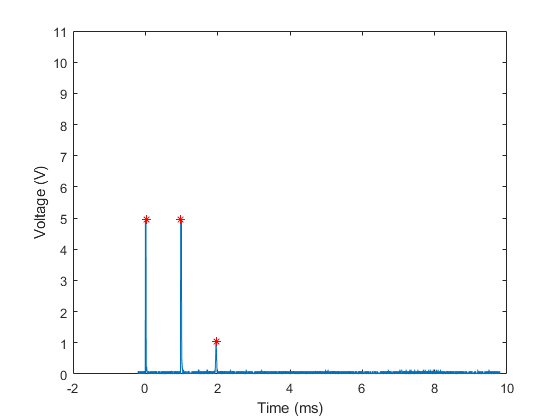

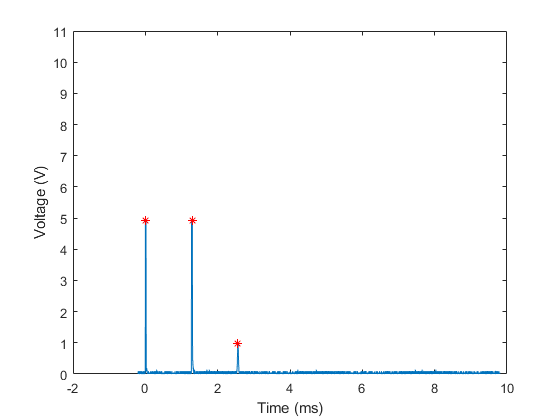

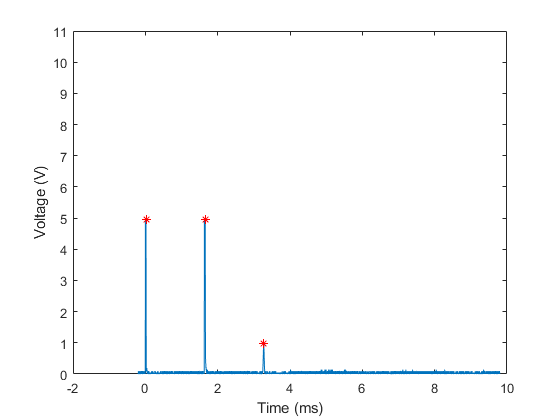

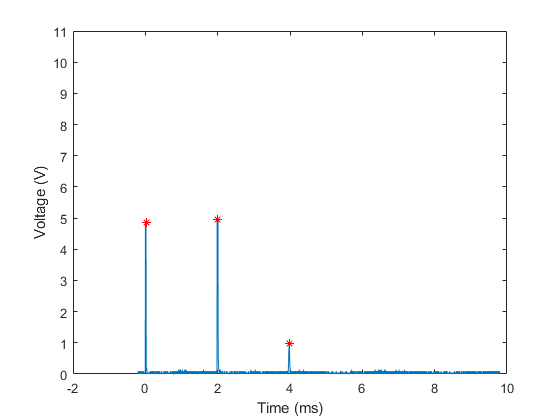

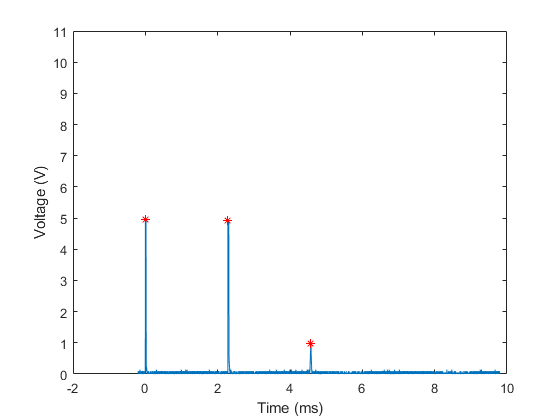

pulse_seperation =     0.1419    0.6940    0.4351    0.9566    1.2980    1.6377    1.9664    2.2817    2.6304    2.9560    3.2500    3.6070    3.9427    4.2087    4.5608    5.1174    5.7254    6.3650    6.9542    7.5904    8.1768


spinEchoAmp =     1.0765    1.0765    1.1234    1.0298    0.9829    0.9829    0.9829    0.9829    0.9361    0.8894    0.8425    0.8425    0.7490    0.7957    0.7490    0.7020    0.6553    0.5616    0.5149    0.4680    0.4212


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =     0.0737    0.0737    0.1164    0.0293   -0.0173   -0.0173   -0.0173   -0.0173   -0.0660   -0.1172   -0.1714   -0.1714   -0.2891   -0.2285   -0.2891   -0.3538   -0.4227   -0.5769   -0.6638   -0.7593   -0.8646


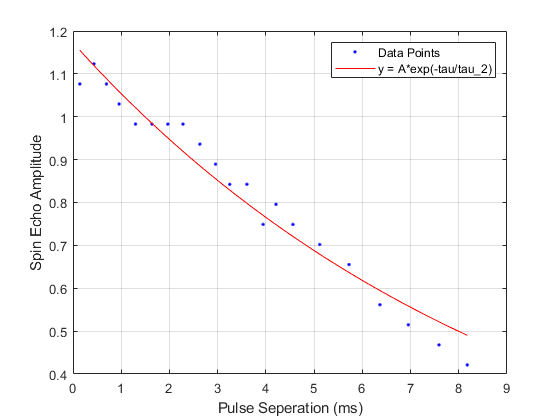

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =       1.172  (1.13, 1.215)
       t_2 =       9.375  (8.378, 10.37)

gof = struct with fields:
           sse: 0.0345
       rsquare: 0.9611
           dfe: 19
    adjrsquare: 0.9590
          rmse: 0.0426


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

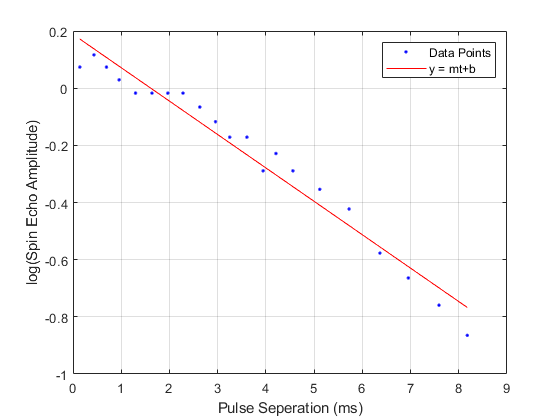

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 3.547 and std 2.412
     Coefficients (with 95% confidence bounds):
       p1 =     -0.2819  (-0.3082, -0.2556)
       p2 =     -0.2262  (-0.2519, -0.2005)

gof = struct with fields:
           sse: 0.0601
       rsquare: 0.9636
           dfe: 19
    adjrsquare: 0.9617
          rmse: 0.0562


9.37[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:36:59


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0461713906311539 0.0971317812358475];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Exponential Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on
end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

